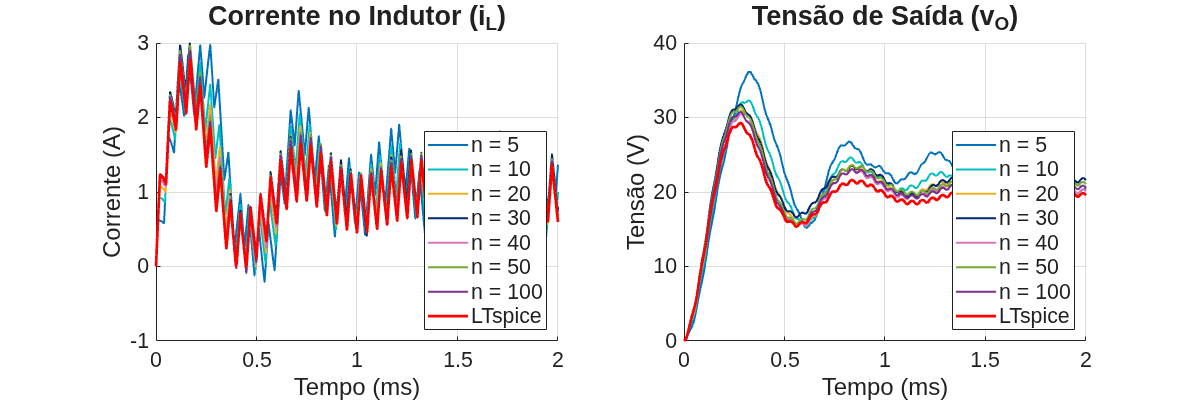

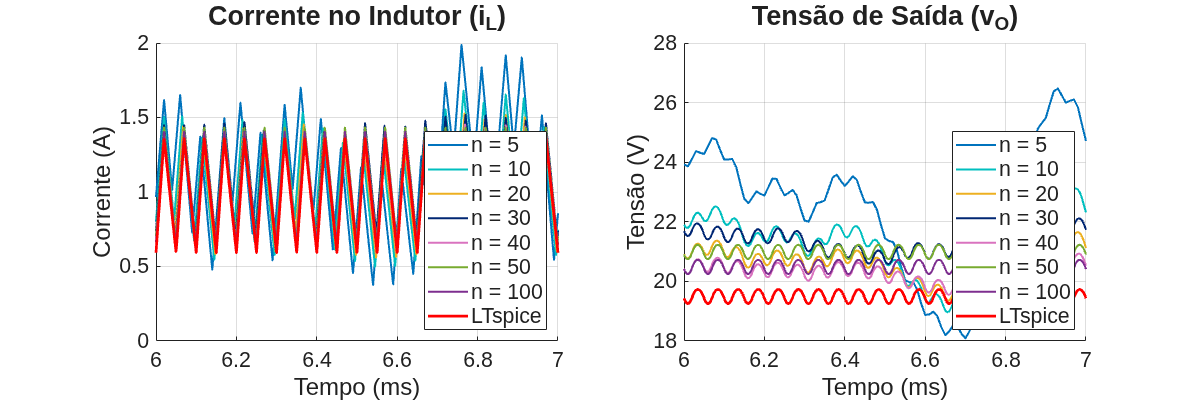

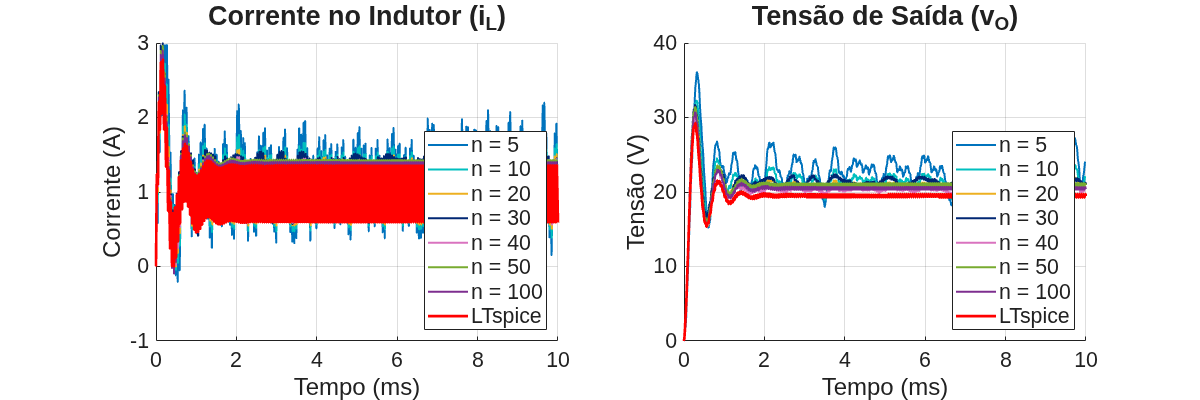


% =========================================================================
% Simulação Discreta de Conversor Buck (Método de Tustin) + LTspice
% =========================================================================
clear; clc; close all;

% Descobre automaticamente a pasta onde este script (.mlx) está salvo
documento_ativo = matlab.desktop.editor.getActive();
pasta_deste_script = fileparts(documento_ativo.Filename);

% Muda o diretório de trabalho do MATLAB para essa pasta (se ela existir)
if ~isempty(pasta_deste_script)
    cd(pasta_deste_script);
end

t_total = double(10e-3);     % Tempo total de simulação (s) 10ms

% Vetor com os diferentes valores de T_div que você quer testar
T_div_testes = double([5, 10, 20, 30, 40, 50, 100]); 

% Estruturas do tipo cell para armazenar vetores de tamanhos diferentes
resultados_t = cell(1, length(T_div_testes));
resultados_iL = cell(1, length(T_div_testes));
resultados_vO = cell(1, length(T_div_testes));

% Loop externo para testar cada valor de T_div
for idx_fdiv = 1:length(T_div_testes)
    T_div = double(T_div_testes(idx_fdiv));

    %% 1. Parâmetros de Simulação e do Conversor
    VS = double(50.0);      % Tensão de entrada (V)
    fs = double(20e3);      % Frequência de chaveamento (Hz)
    D  = double(0.4);       % Razão cíclica nominal
    L  = double(800e-6);    % Indutância (H)
    C  = double(10e-6);     % Capacitância (F)
    R  = double(20.0);      % Resistência de carga (Ohms)

    % Configuração de tempo e discretização
    Ts = double(1.0) / fs;         % Período de chaveamento (s)
    Tsim = double(Ts / T_div);     % Passo de simulação (s) 
    N_steps = double(floor(t_total / Tsim)); % Número total de passos

    %% 2. Constantes de Discretização (Tustin)
    K1 = double(Tsim / (double(2.0) * L));
    K2 = double((double(2.0) * R * C - Tsim) / (double(2.0) * R * C + Tsim));
    K3 = double((R * Tsim) / (double(2.0) * R * C + Tsim));

    % Constantes auxiliares para resolução do laço algébrico
    Den_alg = double(double(1.0) + double(K1 * K3));
    K_iL1   = double(double(1.0) - double(K1 * K3));
    K_iL2   = double(K1 * double(double(1.0) + K2));

    %% 3. Inicialização das Variáveis de Estado
    vs_old = double(VS);
    vs_new = double(VS);
    iL_old = double(0.0); 
    vO_old = double(0.0);

    % Vetores (pré-alocação explícita em double)
    t_array = double(double(0:N_steps-1) * Tsim);
    iL_array = zeros(1, N_steps, 'double');
    vO_array = zeros(1, N_steps, 'double');

    % Armazena as condições iniciais
    iL_array(1) = iL_old;
    vO_array(1) = vO_old;

    %% 4. Loop Principal de Simulação
    for k = 2:N_steps
        t_atual = double(t_array(k));
        
        vs_new = double(VS); 
        
        % Mapeia o tempo contínuo para a posição dentro do período
        t_no_periodo = double(mod(t_atual, Ts)); 
        
        if t_no_periodo < double(D * Ts)
            chave_fechada = true;
        else
            chave_fechada = false;
        end
        
        % --- Atualização das Variáveis de Estado ---
        if chave_fechada
            iL_new = double((double(iL_old * K_iL1) + double(K1 * (vs_new + vs_old)) - double(K_iL2 * vO_old)) / Den_alg);
        else
            iL_new = double((double(iL_old * K_iL1) - double(K_iL2 * vO_old)) / Den_alg);
        end
        
        vO_new = double(double(K2 * vO_old) + double(K3 * (iL_new + iL_old)));
        
        % --- Armazenamento para os Gráficos ---
        iL_array(k) = iL_new;
        vO_array(k) = vO_new;
        
        % --- Preparação para o Próximo Passo ---
        vs_old = vs_new;
        iL_old = iL_new;
        vO_old = vO_new;
    end
    
    resultados_t{idx_fdiv} = t_array;
    resultados_iL{idx_fdiv} = iL_array;
    resultados_vO{idx_fdiv} = vO_array;
end

%% 4.5 Leitura dos Dados do LTspice
% Lê o arquivo buck_ideal.txt (pula o cabeçalho automaticamente)
% Colunas esperadas: time, V(n002), I(L1)
dados_lt = readmatrix('buck_ideal_20.txt');
t_lt     = dados_lt(:, 1);
vO_lt    = dados_lt(:, 2);
iL_lt    = dados_lt(:, 3);

%% 5. Geração dos Gráficos

% Define os intervalos de tempo [t_inicial, t_final] em segundos para cada gráfico
intervalos = [
    0.0,     2e-3;   % 0 a 0.25 ms (Transiente inicial)
    6e-3, 7e-3; % 50 a 50.25 ms (Meio da simulação - Regime permanente)
    0.0,     t_total   % 0 a 100 ms (Simulação completa)
];

% Títulos correspondentes
titulos = {'0 a 0.25 ms', '7 a 7.45 ms', '0 a 10 ms'};

% Cria as legendas do MATLAB e adiciona a do LTspice ao final
legendas = cell(1, length(T_div_testes));
for i = 1:length(T_div_testes)
    legendas{i} = ['n = ' num2str(double(T_div_testes(i)))];
end
legendas_com_ltspice = [legendas, {'LTspice'}];

% Definição manual de uma paleta de cores distinta e de alto contraste
cores_matlab = [
    0.00, 0.45, 0.74; % Azul vibrante (n = 5)
    0.00, 0.75, 0.75; % Ciano (Azul claro) (n = 10)
    0.93, 0.69, 0.13; % Amarelo mostarda (n = 25)
    0.00, 0.15, 0.45; % AZUL MARINHO ESCURO (n = 30) - Frio e distinto
    0.85, 0.45, 0.75; % Rosa/Magenta suave (n = 40)
    0.47, 0.67, 0.19; % Verde folha (n = 50)
    0.49, 0.18, 0.56  % Roxo escuro (n = 100)
];

for n = 1:size(intervalos, 1)
    
    t_min = intervalos(n, 1);
    t_max = intervalos(n, 2);

    % Ajustado o tamanho da janela (Position) para acomodar melhor gráficos lado a lado
    figure('Name',['Resposta - ' titulos{n}], ...
        'NumberTitle','off', 'Position', [100, 100, 1200, 400]);

    % ==========================================
    % Corrente do indutor
    % ==========================================
    subplot(1,2,1); 
    hold on;
    % Plota os dados do MATLAB com cores customizadas e linha um pouco mais espessa
    for i = 1:length(T_div_testes)
        t_aux = double(resultados_t{i});
        iL_aux = double(resultados_iL{i});

        % Filtra usando os limites inferior e superior do intervalo
        idx = (t_aux >= t_min) & (t_aux <= t_max);
        plot(t_aux(idx)*double(1e3), iL_aux(idx), 'Color', cores_matlab(i,:), 'LineWidth', 1.5);
    end
    
    % Plota os dados do LTspice
    idx_lt = (t_lt >= t_min) & (t_lt <= t_max);
    plot(t_lt(idx_lt)*double(1e3), iL_lt(idx_lt), 'r-', 'LineWidth', 2.0);

    hold off;
    grid on;
    
    % --- Configurações de tamanho de fonte dos eixos ---
    set(gca, 'FontSize', 16); % Aumenta ainda mais o tamanho dos números (ticks)
    xlabel('Tempo (ms)', 'FontSize', 18); % Aumenta ainda mais o texto do eixo X
    ylabel('Corrente (A)', 'FontSize', 18); % Aumenta ainda mais o texto do eixo Y
    title('Corrente no Indutor (i_L)', 'FontSize', 20); % Aumenta ainda mais o título
    
    % --- Legenda com tamanho de fonte aumentado ---
    legend(legendas_com_ltspice, 'Location', 'southeast', 'FontSize', 16);

    % ==========================================
    % Tensão de saída
    % ==========================================
    subplot(1,2,2); 
    hold on;
    % Plota os dados do MATLAB com cores customizadas
    for i = 1:length(T_div_testes)
        t_aux = double(resultados_t{i});
        vO_aux = double(resultados_vO{i});

        % Filtra usando os limites inferior e superior do intervalo
        idx = (t_aux >= t_min) & (t_aux <= t_max);
        plot(t_aux(idx)*double(1e3), vO_aux(idx), 'Color', cores_matlab(i,:), 'LineWidth', 1.5);
    end
    
    % Plota os dados do LTspice
    idx_lt = (t_lt >= t_min) & (t_lt <= t_max);
    plot(t_lt(idx_lt)*double(1e3), vO_lt(idx_lt), 'r-', 'LineWidth', 2.0);

    hold off;
    grid on;
    
    % --- Configurações de tamanho de fonte dos eixos ---
    set(gca, 'FontSize', 16); % Aumenta ainda mais o tamanho dos números (ticks)
    xlabel('Tempo (ms)', 'FontSize', 18); % Aumenta ainda mais o texto do eixo X
    ylabel('Tensão (V)', 'FontSize', 18); % Aumenta ainda mais o texto do eixo Y
    title('Tensão de Saída (v_O)', 'FontSize', 20); % Aumenta ainda mais o título
    
    % --- Legenda com tamanho de fonte aumentado ---
    legend(legendas_com_ltspice, 'Location', 'southeast', 'FontSize', 16);
end